# Fill Missing Values

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

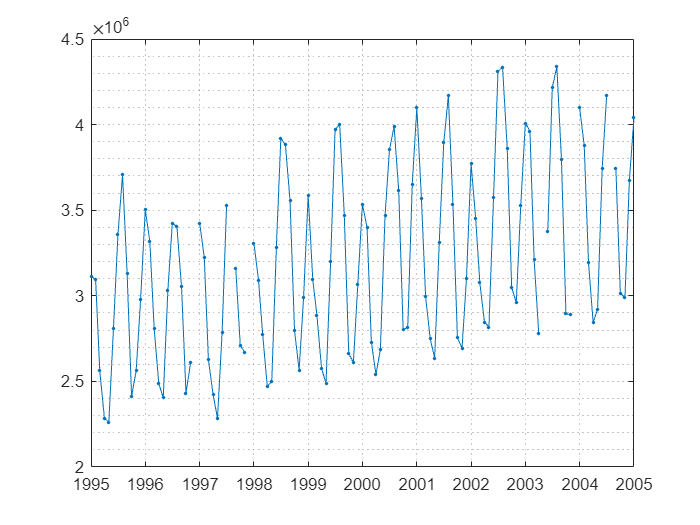

usage = table2array(readtable("../data/electricityData.xlsx", "Sheet", "usage", 'ReadVariableNames', false));
dates = table2array(readtable("../data/electricityData.xlsx", "Sheet", "dates", 'ReadVariableNames', false));
plot(dates, usage(:, 1), ".-")
grid minor
xlim(datetime([1995,2005], 1, 1))

## Task 1

linfill = fillmissing(usage, "linear")

linfill = 1.0e+07 *

    0.3078    0.2016    0.2425    0.7770
    0.2661    0.2033    0.2665    0.7620
    0.2319    0.1870    0.2479    0.6905
    0.2173    0.1883    0.2541    0.6836
    0.2028    0.1901    0.2541    0.6715
    0.2463    0.2154    0.2689    0.7568
    0.2933    0.2289    0.2700    0.8116
    0.2857    0.2294    0.2711    0.8133
    0.2875    0.2310    0.2720    0.8173
    0.2245    0.2035    0.2644    0.7171


## Task 2

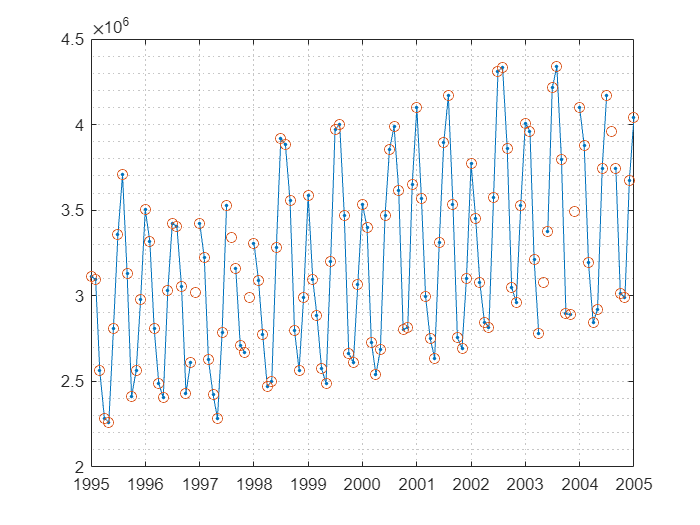

hold on
plot(dates, linfill(:, 1), "o")
hold off

## Task 3

cubefill = fillmissing(usage, "pchip")

cubefill = 1.0e+07 *

    0.3078    0.2016    0.2425    0.7770
    0.2661    0.2033    0.2665    0.7620
    0.2319    0.1870    0.2479    0.6905
    0.2173    0.1883    0.2541    0.6836
    0.2028    0.1901    0.2541    0.6715
    0.2463    0.2154    0.2689    0.7568
    0.2933    0.2289    0.2703    0.8116
    0.2857    0.2294    0.2711    0.8133
    0.2875    0.2310    0.2720    0.8173
    0.2245    0.2035    0.2644    0.7171


## Task 4

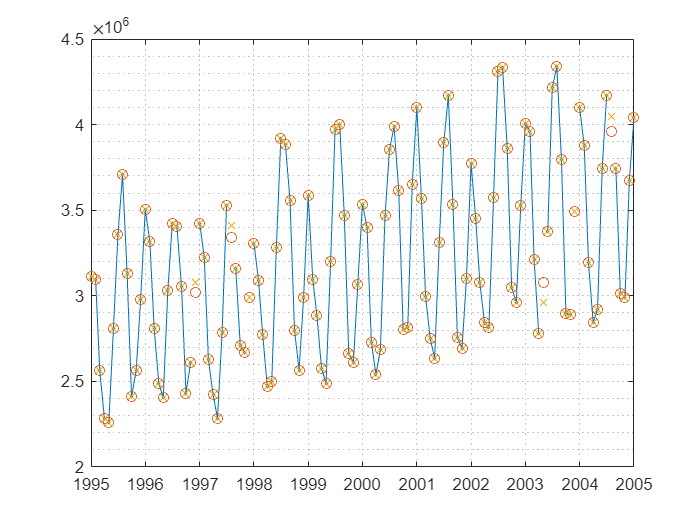

hold on
plot(dates, cubefill(:, 1), "x")
hold off